# Worksheet 5: Mechanical Systems

#### Due Monday, November 23

This worksheet is a bit different from the others: there are some sections that everyone will do and some sections where you'll choose from among options. At each table you should be sure there's at least one person doing each of the options in section 3, so that in section 4 you'll be able to discuss all of the options.   

As usual, we are expecting that you will be able to start in studio during our three class sessions this week, and comfortably finish as homework. You are welcome to work ahead, but you should plan to use the class time to collaborate with the other students at your studio table. 

Note that this worksheet will continue over the weekend and be due on Monday, November 23, before we go on break for Thanksgiving. 

***Note:**** When I put images into this live script, MATLAB started running out of memory. So I moved them to the *`images/`* folder. The name of each image is the question it corresponds to (ex. *`3B2_2.png`* is Image #2 for Question 3.B.2). Sadly, I had to extract the images by screenshotting them. I'm sorry.*

### Learning Objectives

After completing this worksheet, you should be able to:

- Represent a mechanical system with a schematic diagram and a free body diagram.  

- Represent a mechanical system with one or more second order ODEs and a system of first order ODEs. 

- Identify different phases of motion and the triggers that signal the transitions between them. 

- Simulate a simple mechanical system, using vectors and computational tools such as ode events. 

## 1. Reading Questions

***Everyone should complete section 1.***

Please read chapters 11 and 12 in the Robot Book, then answer the following questions. 

1.1. What's the basic idea behind how we use ode45 to solve a second order ODE? 

**Response:**

Since ode45 cannot model a second order ODE, we use an additional state variable to represent the first order derivitative. The rate of change of this variable is the second order derivative, and it is the rate of change for the original state variable in question.

1.2. Conceptually, what is an event? In MATLAB, what are the three things we need to define in an event function? 

**Response:**

The value of the event (event fires when value crosses zero), if the event should terminate ode45 when triggered, and if the event should fire when value becomes negative, becomes positive, or both.

1.3. How have we used the word *vector* thus far with respect to MATLAB? What is a *spatial vector*? What is a *unit vector*?

**Response:**

We've been using vector to mean a one-dimensional array (ie. a matrix with only one dimension that doesn't equal 1). A spatial vector is a point in nD space, or a quantity in nD space with both direction and magnitude. A unit vector is a spatial vector with a magnitude equal to 1.

## 2. Abstractions, Diagrams, and Equations 

***Everyone should complete section 2. ***

In exercise 2 of chapter 11, the Robot Book refers to the question: If the earth suddenly stopped in its orbit, how long would it take the to hit the sun? We're going to think about a one-dimensional treatment of this question, in which we only have to consider the motion of the earth directly toward the sun. In case you don't have them handy from the book exercise, here are a few bits of useful information:

law of universal gravitation: $F=G\frac{m_1 m_2 }{r^2 }$

mass of the earth: 5.97e24 kg

mass of the sun: 1.99e30 kg

distance between the earth and the sun: 1.50e11 m


$$G=6\ldotp 67\times {10}^{-11} \frac{N\cdot m^2 }{{\textrm{kg}}^2 }$$


2.1.  Draw a schematic diagram, showing your system, the key parts, the key interactions, and your coordinate system. How did you decide where to put the origin of your coordinate system? 

**Response: **

I put the origin of the (one dimensional) coordinate system at the center of the sun, because, for the purposes of this model, the sun is our reference frame, and we don't really care about its movement.

*See images folder.*

2.2.  If there are multiple phases of motion or events that we should attend to, draw a series of sketches to capture all the phases or to show the events.  

**Response: **

N/A

2.3.  Which part or parts of the system are we keeping track of? (This is analogous to deciding which stock(s) we want to include in a stock and flow diagram.) Draw a clearly labeled free body diagram for each part you think we should be tracking. 

**Response: **

*See images folder.*

2.4.  Based on your free body diagram, write the appropriate second order ODE to describe this system. What happens when the distance between the earth and the sun goes to zero? 

**Response: **


$$\frac{\textrm{dv}}{\textrm{dt}}=a=\frac{\overrightarrow{\;F} }{m}=-G\;\frac{m_1 m_2 }{r^2 }$$


When r = 0, the Earth no longer exists and so the ODEs are undefined

2.5.  Convert your second order ODE into the corresponding system of first order ODEs. Check that the signs are correct. 

**Response: **


$$\begin{array}{l}
\frac{\textrm{dv}}{\textrm{dt}}=a=\frac{\overrightarrow{\;F} }{m}=-G\;\frac{m_1 m_2 }{r^2 }\\
\frac{\textrm{dr}}{\textrm{dt}}=v
\end{array}$$


When r = 0, the Earth no longer exists and so the ODEs are undefined

***PROGRESS CHECK: We are expecting you to complete the questions above before class on Wednesday. If you get stuck, we suggest consulting a CA or someone at your studio table before you come to class; this will help everyone benefit from collaborating during the studio time.***

## 3. Simulations 

***Each of you should complete either 3A, 3B, or 3C, including all sub-parts and questions of whichever simulation you complete. At each table, there should be at least one person completing each, so that as a table you've covered all three.***

This is where we split up! Each of you will now work on building one simulation. Each will give you practice with the same key concepts. In addition, the 2-D orbital model will provide extra practice with vectors, the hopper model will provide extra practice with phases of motion, and the Manny Ramirez model will provide extra practice with root finding and optimization. You'll all discuss all three models together after you build the simulations. 

If you're not sure how to split up to work on the separate models, you might consider whether anyone is particularly interested in one or another of the models as well as whether anyone is particularly interested in working more with a partner than solo. You can also flip a coin or draw names from a hat, or use whatever other method you like for dividing and conquering. 

### 3A. Earth Orbiting the Sun

You've already worked on a one-dimensional model of the earth falling into the sun. Now you'll build a two-dimensional model in which the earth orbits the sun. You should have the constants and equations you need from the 1-D version above.

3A.1.  First, implement the one-dimensional model you developed in section 2. Plot the results. What is the answer to the original question? (If the earth suddenly stopped in its orbit, how long would it take the to hit the sun?)

**Response:**

% Your response here

% Your response here

3A.2.  Now consider a two-dimensional coordinate system in which the earth can orbit the sun. What is the initial position of the earth in this coordinate system?

**Response: **

% Your response here

3A.3.  Draw a schematic diagram with additional frames as needed to represent phases of motion. Be sure to include your coordinate system and indicate which directions are positive for x and y. Clearly show the vector that defines the position of the earth and a vector that depicts the velocity of the earth. How do the directions of these vectors relate to the direction of the gravitational force? 

**Response:**

% Your response here 

3A.4.  Draw the appropriate free body diagram(s). Again, include your coordinate system and indicate which directions are positive for x and y. 

**Response: **

% Your response here 

3A.5.  Write the second order ODE and the system of first order ODEs. How are these different now that you're using vectors rather than scalars? 

**Response: **

% Your response here

3A.6.  Create a simulation of this model and run it for the case in which the initial velocity of the earth is zero. Plot the results here. The results should be the same as the 1-D case; why? 

**Response:**

% Your response here

3A.7.  Now run your model with a positive velocity that's orthogonal to the position vector. Call it here and plot the results.

(If you want to start with the earth moving at its actual orbital speed, you can estimate or look up what that speed should be. Feel free to experiment with other speeds as well.)

% Your response here

***PROGRESS CHECK: If you are working on the 2-D orbital model, we are expecting you to have a full draft of your code by class on Friday, even if it doesn't all work yet. We're expecting you to complete all of the questions in section 3A before class on Monday. If you get stuck, we suggest consulting a CA or someone at your studio table before you come to class; this will help everyone benefit from collaborating during the studio time.***

### 3B. A Simple Hopper (Ari)

Consider a simple hopper: a relatively lightweight rod with a heavier 'reaction mass' that's attached via springs or latex tubing to the rod. The hopper is loaded by stretching the tubing (or springs); when the hopper is triggered, the reaction mass accelerates up and the hopper leaps. 

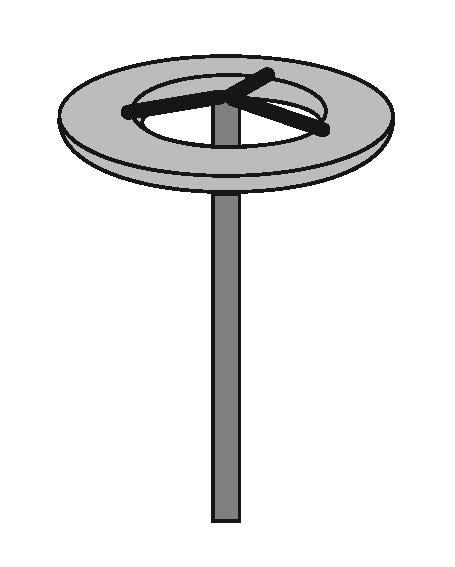

3B.1.  What are the key parts of this hopper and how do they interact? Draw a simple schematic of the hopper at rest and label the parts and interactions. Remember that the hopper probably isn't floating in space the whole time. 

**Response: **

*See images folder.*

3B.2.  How many phases of motion do you need to capture and consider separately to understand how the hopper launches? Start with a series of quick sketches to show the hopper's movement, then choose the key phases of motion and draw a more detailed schematic for each one. (Include your sketches and your more detailed series of schematics both in your response.) Be sure to include your coordinate system and indicate which directions are positive for x and y. Why did you choose this coordinate system? 

**Response:**

*See images folder.*

3B.3.  Draw the appropriate free body diagrams: include as many as are needed to capture the key phases of motion. Again, include your coordinate system and indicate which directions are positive for x and y. 

**Response: **

*See images folder.*

3B.4.  Write the second order ODE(s) and the corresponding system(s) of first order ODEs. How many second order ODEs do you need to write to adequately model all the phases of motion? 

**Response: **

% Your response here

3B.5.  Create a simulation of this model. Call it here and plot the results. You should include an event function and use ODE events to stop the simulation at the appropriate moment. 

**Response:**

[T, D, debug] = model();
clf; hold on;
plot(T, D(:, 1));
plot(T, D(:, 2), "--");
%plot(T, D(:, 3));
%plot(T, D(:, 4), "--");
%plot(debug(:, 1), debug(:, 2), ".");
%plot(debug(:, 1), debug(:, 3), ".");
%plot(debug(:, 1), debug(:, 4), ".");
%plot(debug(:, 1), debug(:, 5), ".");
%ylim([0 10])
legend("Z_R", "Z_D", "V_R", "V_D"); %, "d elastic", "F elastic", "dvdt rod", "dvdt disk");

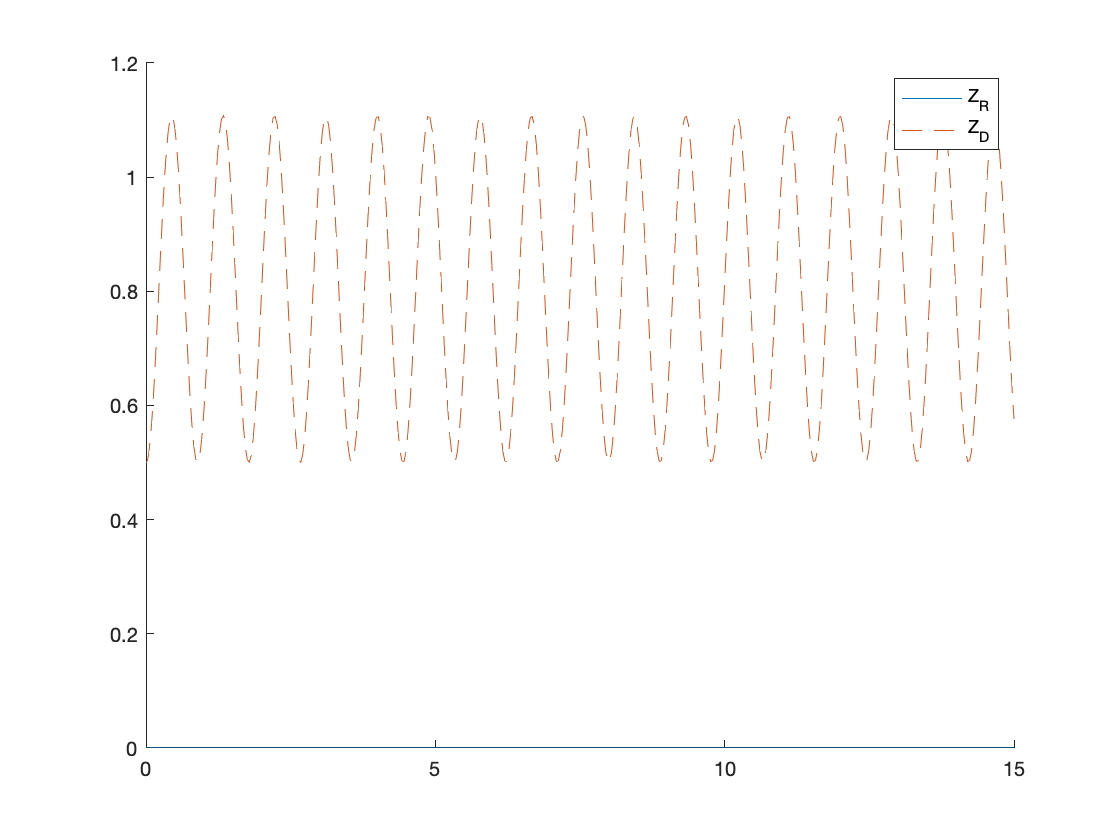

hold off;

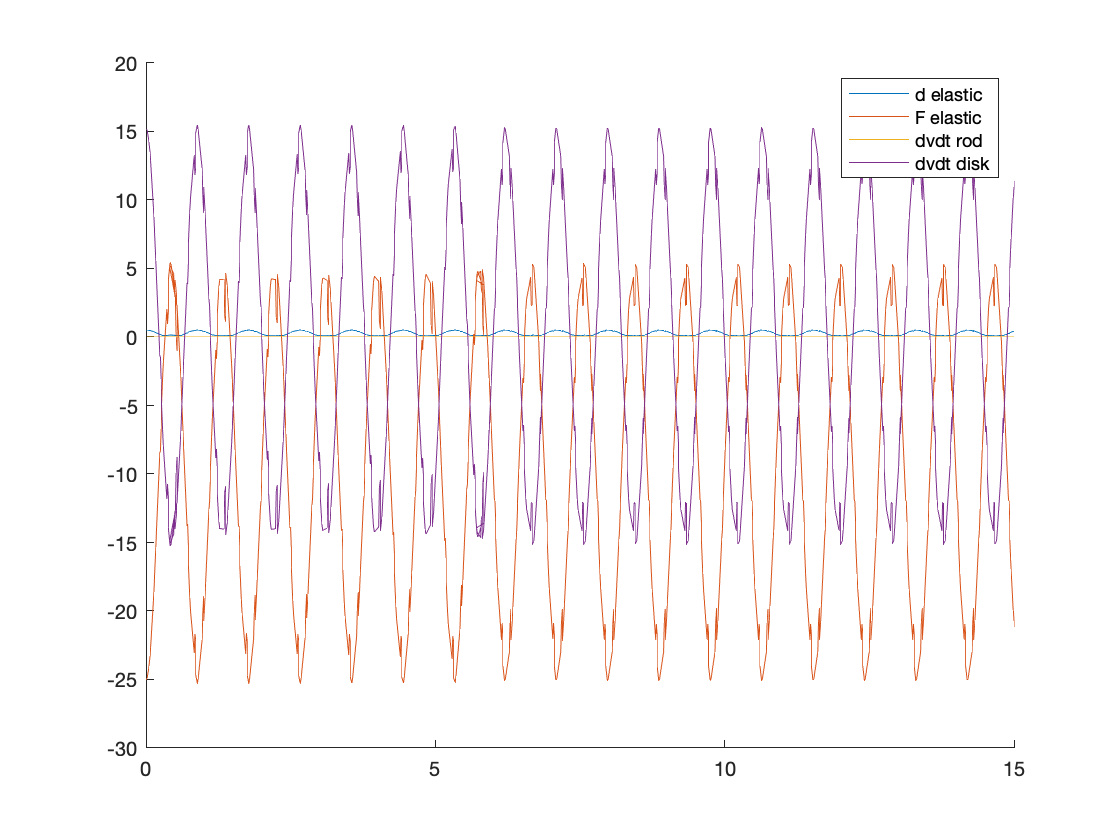

figure; hold on;
plot(debug(:, 1), debug(:, 2));
plot(debug(:, 1), debug(:, 3));
plot(debug(:, 1), debug(:, 4));
plot(debug(:, 1), debug(:, 5));
legend("d elastic", "F elastic", "dvdt rod", "dvdt disk");
hold off;

mean(D(:, 2))

ans = 0.7873

***PROGRESS CHECK: If you are working on the hopper model, we are expecting you to have a full draft of your code by class on Friday, even if it doesn't all work yet. We're expecting you to complete all of the questions in section 3B before class on Monday. If you get stuck, we suggest consulting a CA or someone at your studio table before you come to class; this will help everyone benefit from collaborating during the studio time.***

### 3C. Manny Ramirez and the Green Monster  

This model is drawn from the Robot Book (chapter 13, exercise 1):

"Manny Ramirez is a former member of the Boston Red Sox who was famous for his relaxed attitude. The goal of this exercise is to solve the following Manny-inspired problem: What is the minimum effort required to hit a home run in Fenway Park?

Fenway Park is a baseball stadium in Boston, Massachusetts. One of its most famous features is the 'Green Monster,' which is a wall in left field that is unusually close ot home plate, only 310 feet away. To compensate for the short distance, the wall is unusually high, at 37 feet." 

3C.1.  Draw a schematic diagram — with additional frames as needed to represent phases of motion — that includes (with labels!) all important parts of the system. Be sure to include your coordinate system and indicate which directions are positive for x and y.  

**Response: **

% Your response here

3C.2.  Draw the appropriate free body diagrams; consider whether you want to include drag in your initial model. Again, include your coordinate system and indicate which directions are positive for x and y. 

**Response:**

% Your response here 

3C.3.  Write the second order ODE and the corresponding system of first order ODEs.  

**Response: **

% Your response here 

3C.4.  Create a basic simulation of this model. Call it here and plot the results. You should include an event function and use ODE events to stop the simulation when the ball either hits the ground or reaches the wall. Return the final height of the ball. Don't worry about solving the Manny problem yet. 

**Response: **

% Your response here

3C.5.  Now solve the Manny problem in two steps, per the Robot Book: 

- For a given velocity, find the launch angle that maximizes the height of the ball when it reaches the wall. Notice that this is not quite the same as the angle that maximizes the distance the ball travels. 

- Find the minimal velocity that clears the wall, given that it has the optimal launch angle. Hint: this is actually a root-finding problem, not an optimization problem. 

Modify your code as needed to solve the Manny problem. You can call your function below, and then report (1) the optimal launch angle and (2) the minimal velocity needed for the ball to clear the wall. 

**Response:**

% Your response here

% Your response here 

***PROGRESS CHECK: If you are working on the Manny Ramirez model, we are expecting you to have a full draft of your code by class on Friday, even if it doesn't all work yet. We're expecting you to complete all of the questions in section 3C before class on Monday. If you get stuck, we suggest consulting a CA or someone at your studio table before you come to class; this will help everyone benefit from collaborating during the studio time.***

## 4. Peer to Peer Learning 

***Everyone will come back together again to jointly complete section 4. ***

Even if you haven't all fully completed your simulations, we want you to reconvene and talk about what you've learned from your work thus far. 

4.1.  Start by opening up the solution code so you can refer to it during your discussion and compare your results with the code we've provided to you. 

Whoever worked on the 2-D orbital model: Share with the rest of your table the code you've written thus far and any figures you've produced at this point. Explain your use of position vectors to define the position of the earth, including defining your coordinate system and showing how you used ode45 with these vectors. 

Everyone else at the table, take notes below on what your classmate explains to you. Include a list of key points and any questions that arise in the conversation, along with how you resolve those questions or if they're left unanswered in the discussion. 

**Response: **

- Had some results, but scale might be not quite right

4.2.  Start by opening up the solution code so you can refer to it during your discussion and compare your results with the code we've provided to you. 

Whoever worked on the hopper model: Share with the rest of your table the code you've written thus far and any figures you've produced at this point. Explain your choice of how many phases of motion to distinguish, including showing your diagrams and how you modeled the various phases in the code. 

Everyone else at the table, take notes below on what your classmate explains to you. Include a list of key points and any questions that arise in the conversation, along with how you resolve those questions or if they're left unanswered in the discussion. 

**Response:**

- I wrote this one, so no notes

4.3.  Start by opening up the solution code so you can refer to it during your discussion and compare your results with the code we've provided to you. 

Whoever worked on the Manny Ramirez model: Share with the rest of your table the code you've written thus far and any figures you've produced at this point. Explain your approach to the two steps in 3C.5, both how you thought through it and how you computed the answers.  

Everyone else at the table, take notes below on what your classmate explains to you. Include a list of key points and any questions that arise in the conversation, along with how you resolve those questions or if they're left unanswered in the discussion. 

**Response: **

- No results yet, but lots of good schematics

## 5. Reflection Questions

The purpose of this final section is to give you an opportunity to reflect on your experience in completing the worksheet. This information may be helpful for your studio instructor, but it is mainly intended to be helpful to you.

5.1.  Think about the physics you've been working on. What's been confusing? Where have you gotten stuck or needed help? What questions do you want to ask a CA or instructor in preparation for Project 3? List your questions here (be as specific as possible, but it's also ok if you can only say "I'm confused about _____") as well as your plan for connecting with a CA or instructor to get your questions answered. 

**Response:**

% Your response here

5.2.  Think about the new MATLAB tools you've been using. How are you feeling about these? Are you confident that you'll be able to use them in Project 3? Do you have any questions about these that you want to ask of a CA or instructor in preparation for the project? 

**Response:**

% Your response here

5.3.  We're nearly done with the semester! Hard to believe. What specific learning objectives do you have for yourself for the remainder of ModSim? What steps can you take to work toward those objectives? You might want to refer back to your Project 1 and Project 2 reflections in answering this, and then hold on to your response here and bring it with you to the first day of Project 3 for discussion with your team. 

**Response: **

% Your response here